## Import the image

clc,clear,close all;
pic = imread('D:\2ZYHfiles\实验数据汇总\成果汇总\论文2-番茄红素\写作进展\图像处理\test.png');

## Crop the image

% Cropped area
%1  [300, 300, 400, 450]        %first sample
%2  [750, 300, 400, 450]        %second sample
%3  [1180, 280, 400, 450]       %third sample
rect = [1, 1, 2000, 2000];      
% Crop the image
cropped_img = imcrop(pic, rect);
pic=cropped_img;
picraw=pic;

## Image extraction process

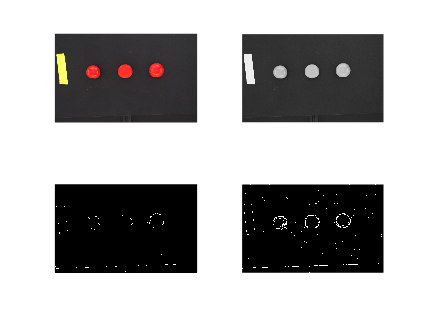

figure;
% Original image
% subplot(2,2,1),imshow(pic),title('1原图');
subplot(2,2,1),imshow(pic);
[rows, cols, colors] = size(pic);
pic_gray = zeros(rows, cols);
pic_gray = uint8(pic_gray);
% Grayscale image
for i = 1:rows
    for j = 1:cols
       %I(i, j) = pic(i, j, 1)*0.30 + pic(i, j, 2)*0.59 + pic(i, j, 3)*0.11;
       I(i, j) = pic(i, j, 1)*0.70 + pic(i, j, 2)*0.2 + pic(i, j, 3)*0.1;
    end
end
% subplot(2,2,2),imshow(I),title('2平均值灰度化');
subplot(2,2,2),imshow(I);
% Find samples
[~,threshold] = edge(I,'sobel');
fudgeFactor = 0.7;
BWs = edge(I,'sobel',threshold * fudgeFactor);
% subplot(2,2,3),imshow(BWs),title('3二元梯度掩膜');
subplot(2,2,3),imshow(BWs);
% Expand the gradient mask
se90 = strel('line',3,90);
se0 = strel('line',3,0);
BWsdil = imdilate(BWs,[se90 se0]);
% subplot(2,2,4),imshow(BWsdil),title('4膨胀梯度掩膜');
subplot(2,2,4),imshow(BWsdil);

% Fill the internal gaps
BWdfill = imfill(BWsdil,'holes');

## Image extraction process

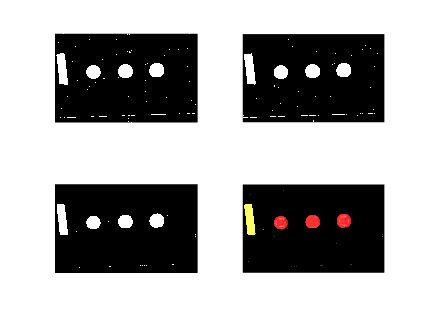

figure;
% Fill the internal gaps
% subplot(2,2,1),imshow(BWdfill),title('5填充后的图像');
subplot(2,2,1),imshow(BWdfill);
% Delete connected objects on the boundary
BWnobord = imclearborder(BWdfill,4);
% subplot(2,2,2),imshow(BWnobord),title('6删除边界连通对象');
subplot(2,2,2),imshow(BWnobord);
% Smoothing samples
seD = strel('diamond',1);
BWfinal = imerode(BWnobord,seD);
BWfinal = imerode(BWfinal,seD);
subplot(2,2,3),imshow(BWfinal);
% title('7平滑后的图像');
% RGB values of sample
S = sum(sum(BWfinal == 1));
target = find(BWfinal == 0);
R = pic(:,:,1);
G = pic(:,:,2);
B = pic(:,:,3);
R(target) = 0;
G(target) = 0;
B(target) = 0;
SR = sum(sum(R));
SG = sum(sum(G));
SB = sum(sum(B));
AR = SR/S;
AG = SG/S;
AB = SB/S;

% RGB results
% subplot(2,2,4), imshow(cat(3, R, G, B)), title('8提取后的目标物');
subplot(2,2,4), imshow(cat(3, R, G, B));

disp(['R均值: ', num2str(AR)]);

R均值: 242.3193


disp(['G均值: ', num2str(AG)]);

G均值: 118.0515


disp(['B均值: ', num2str(AB)]);

B均值: 64.4143


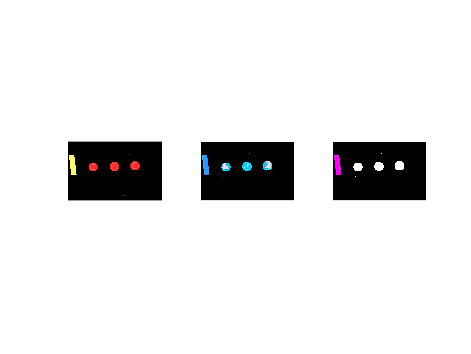

%% RGB → HSV, Gray
% Convert RGB image to HSV and Lab image
rgbImage = cat(3, R, G, B);
hsvImage = rgb2hsv(rgbImage);
labImage = rgb2lab(rgbImage);
% Original RGB image
figure;
subplot(1, 3, 1);
imshow(rgbImage);
% title('原始RGB图像');
% HSV image
subplot(1, 3, 2);
imshow(hsvImage);
% title('转换后的HSV图像');
% Lab image
subplot(1, 3, 3);
imshow(labImage);

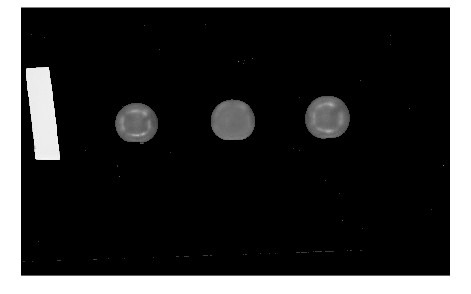

% title('转换后的lab图像');

% Grayscale image
grayImage = rgb2gray(rgbImage);
figure;
imshow(grayImage);

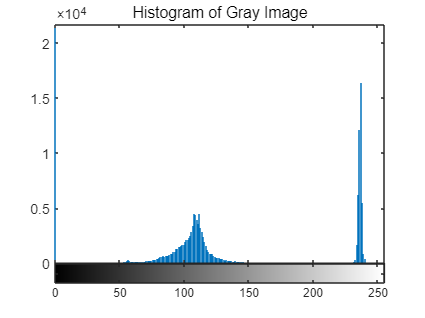

% title('Gray Image');

% Calculate and display the grayscale histogram.
figure;
imhist(grayImage);
title('Histogram of Gray Image');
[counts, binLocations] = imhist(grayImage);
maxCount = max(counts);
ylim([0, maxCount * 0.01]);

## GLCM calculation

% Calculate the gray-level co-occurrence matrix (GLCM) parameters
FinalPic=cat(3, R, G, B);
pic_gray_target = rgb2gray(FinalPic);
glcm_target = graycomatrix(pic_gray_target, 'Offset', [0 1; -1 1; -1 0; -1 -1]);
stats_target = graycoprops(glcm_target, {'contrast', 'correlation', 'energy', 'homogeneity'});
% Show GLCM parameters
% disp('提取后目标物的GLCM参数:');
% disp(['对比度: ', num2str(mean(stats_target.Contrast))]);
% disp(['相关性: ', num2str(mean(stats_target.Correlation))]);
% disp(['能量: ', num2str(mean(stats_target.Energy))]);
% disp(['同质性: ', num2str(mean(stats_target.Homogeneity))]);